global me hbar V0 a d

me=5.68572e-32; 
hbar=6.58199e-16; 

path('C:\Users\edgau\OneDrive - CINVESTAV\Documentos\MATLAB\Examen Max',path);


Free Electron Model

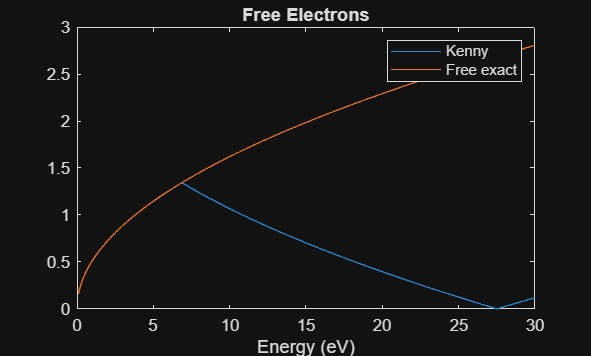

E =  0.1:0.1:30; % Array de energia desde 0 hasta 20eV
a = 4.05/sqrt(3);
d = a/2;
V0 = 0;


[rk, ik] = k(E);
plot(E, rk)

xlabel("Energy (eV)")
title("Free Electrons")
hold on
plot(E,fek(E))

hold off

legend(["Kenny", "Free exact"])

Nearly free electrons 

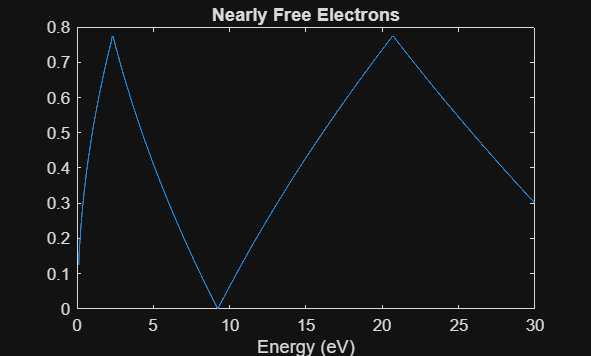

E =  0.1:0.01:30; % Array de energia desde 0 hasta 20eV
a = 4.05;
d = a/2;
V0 = 0.1;

[rk, ik] = k(E);
plot(E, rk)
xlabel("Energy (eV)")
title("Nearly Free Electrons")

stronger potential

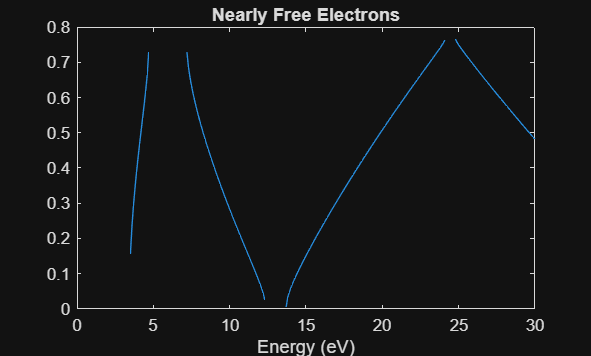

E =  0.1:0.1:30; % Array de energia desde 0 hasta 20eV
a = 4.05;
d =  1;
V0 = 5;

[rk, ik] = k(E);
plot(E, rk)
xlabel("Energy (eV)")
title("Nearly Free Electrons")

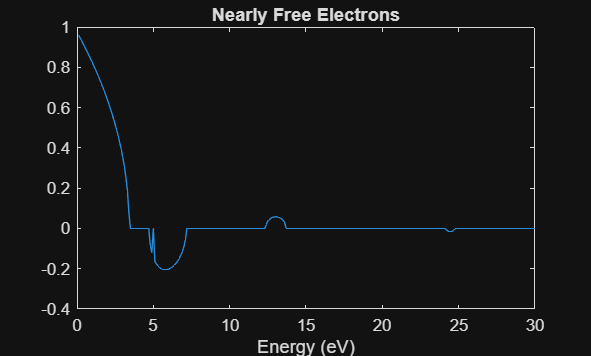



plot(E, ik)
xlabel("Energy (eV)")
title("Nearly Free Electrons")

Masa effectiva

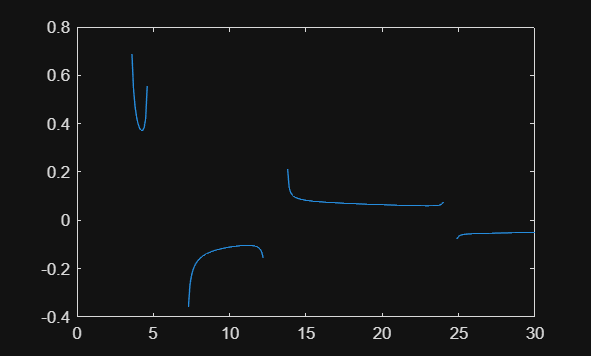



vg = gradient( rk, E); % dydx
plot(E, vg)